# E5 bis

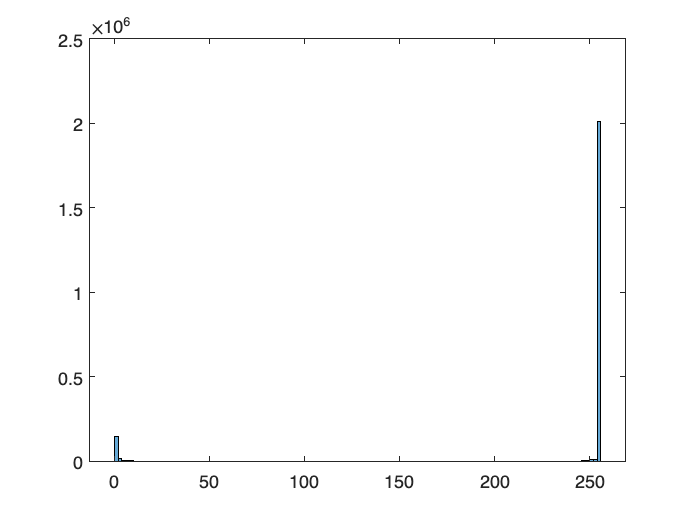

I = rgb2gray(imread("Laberint.png"));
histogram(I);

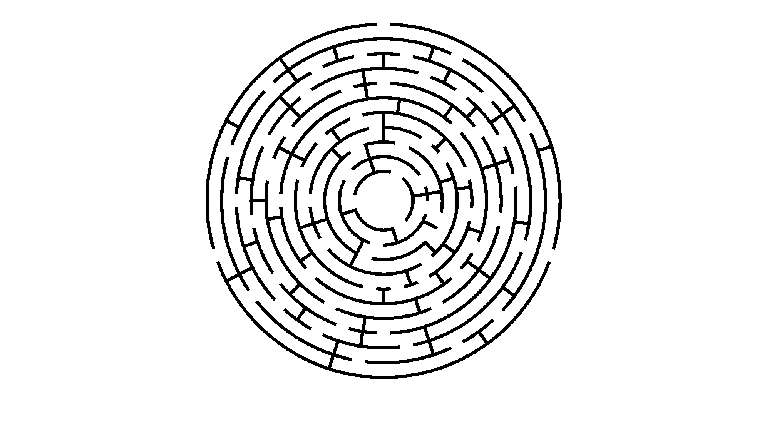


BW = I > 128;
montage({BW});

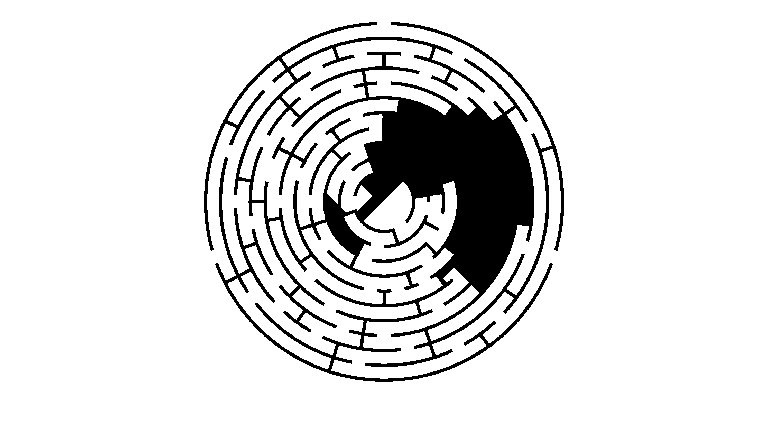

MARK = false(size(BW));
DT = zeros(size(BW));
MARK(1,1) = 1; % posició inicial de la partida
SE = [0 1 0; 1 1 1; 0 1 0];
[f c] = size(BW);
centre = [floor(f/2) floor(c/2)];

fi = false;
while(not(fi))
    MARK = imdilate(MARK,SE) & BW;
    %imshow(MARK);
    DT = DT + MARK;
    if MARK(centre(1),centre(2))
        fi = true;
    end
end

imshow(MARK);

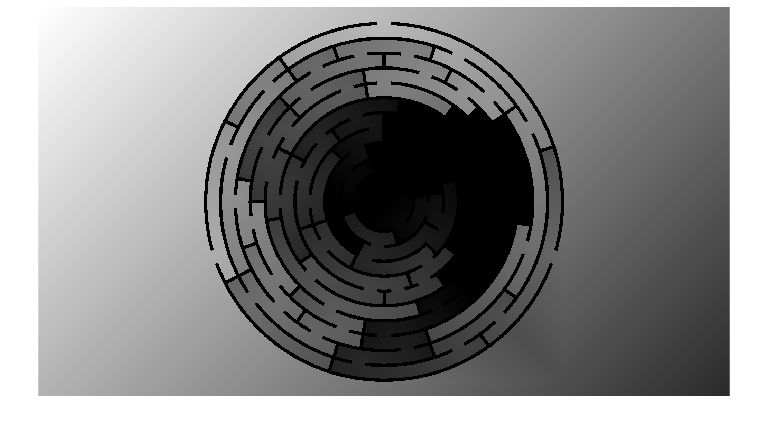

imshow(DT, []);

%DT2 = bwdistgeodesic(BW, )

Esquelets

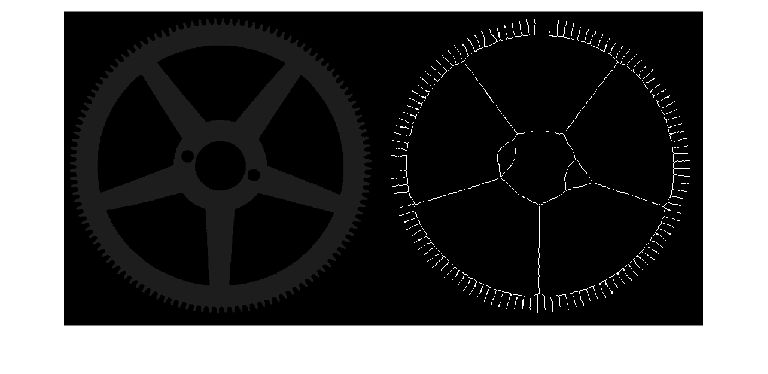

I = rgb2gray(imread("Wheel.bmp"));
BW = I > 15;
SK = bwskel(BW);
montage({I, SK});

SKIZ

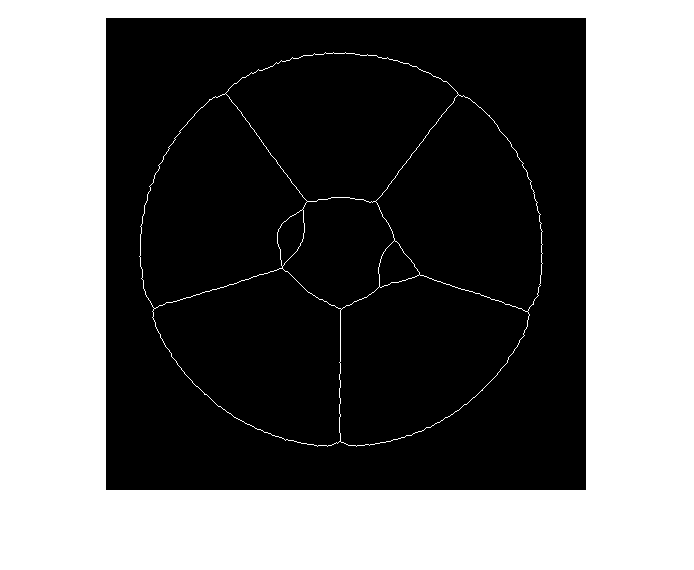

SKIZ = bwmorph(SK, 'spur', Inf);
imshow(SKIZ);

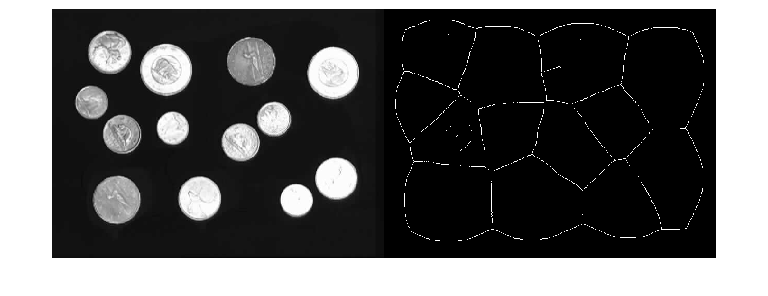

I = imread("money.tif");
BW = I > 100;
SK = bwskel(not(BW)); % esquelet del background
montage({I, SK});

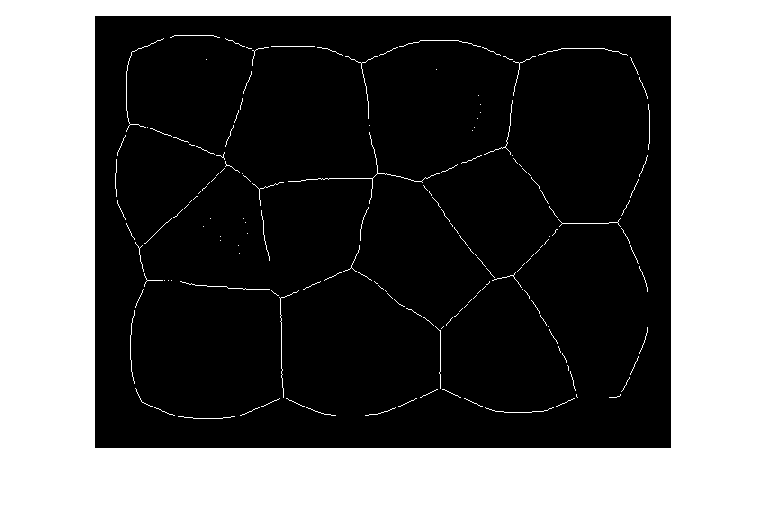

SKIZ = bwmorph(SK, 'spur', Inf);
imshow(SKIZ);

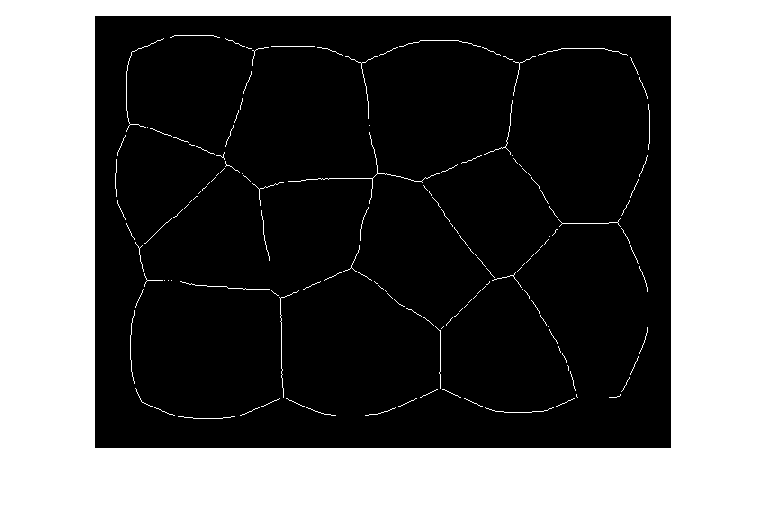


% SKIZP = bwareaopen(SKIZ, 10);
% hit and miss
SKIZP = SKIZ & not(bwhitmiss(SKIZ, [-1 -1 -1; -1 1 -1; -1 -1 -1]));
imshow(SKIZP);

Exercici: indicar en la imatge RGB la cèl·lula més aïllada que no formi part de la vora

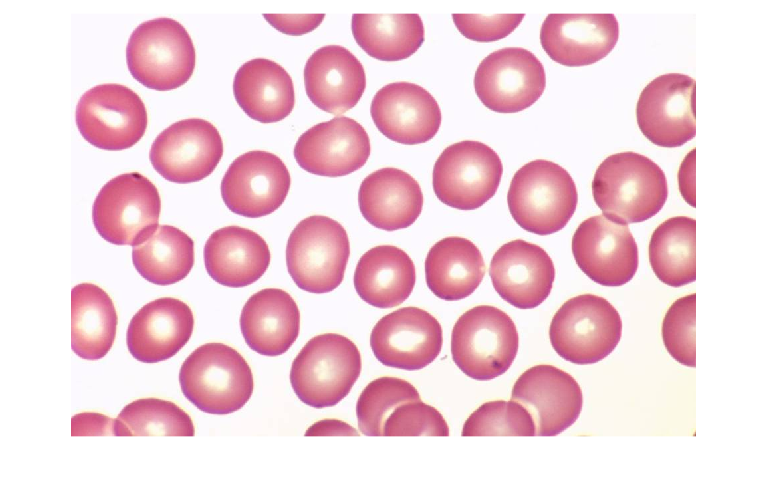

RGB = imread("normal-blood1.jpg");
imshow(RGB);

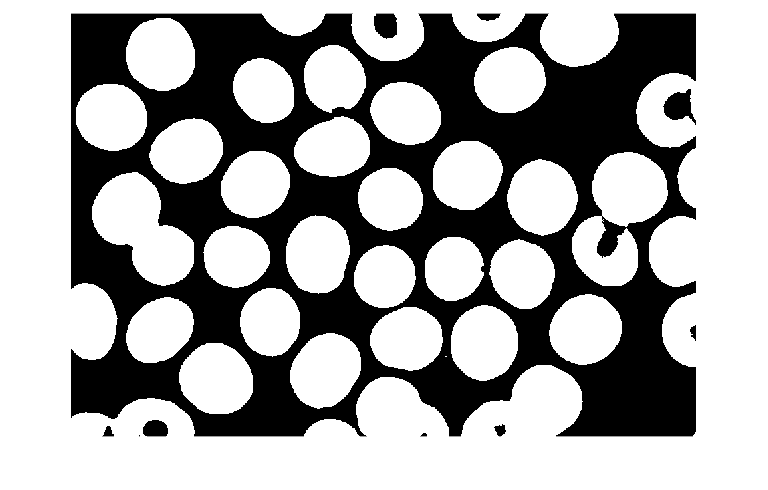


I = rgb2gray(RGB);
t = otsuthresh(imhist(I));
BW = I < t*255;

% omplir forats
MARK = false(size(BW));
MARK(1,:) = 1;
MARK(end,:) = 1;
MARK(:,1) = 1;
MARK(:,end) = 1;

BW = not(imreconstruct(MARK,not(BW)));

imshow(BW);

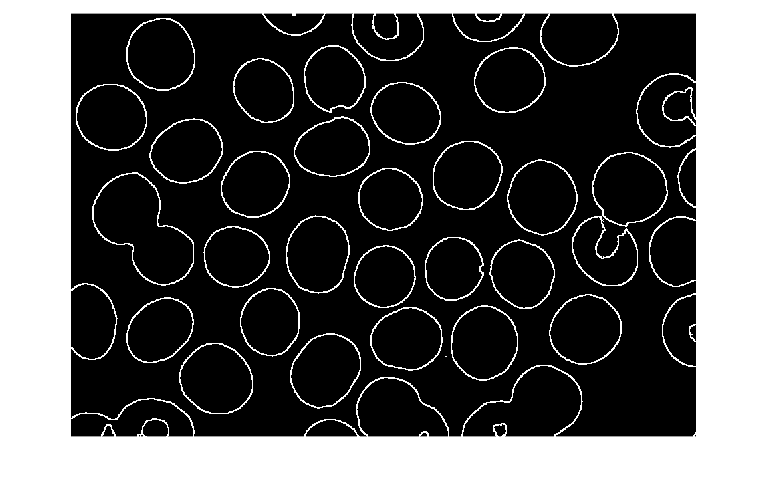


SE = ones(5,5);

% Erosió
BWE = imerode(BW,SE);

% Intern: imatge - erosió
RI = BW & not(BWE);

imshow(RI);

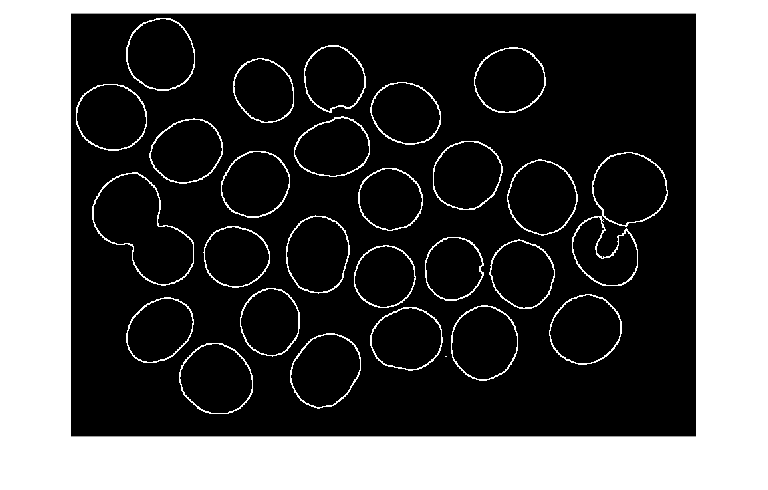


SK = bwskel(not(BW));
SKIZ = bwmorph(SK, 'spur', Inf);
SKIZP = SKIZ & not(bwhitmiss(SKIZ, [-1 -1 -1; -1 1 -1; -1 -1 -1]));
%imshow(SKIZP|REC);

% transformada de la distancia
TD = bwdist(SKIZP);

% eliminem les vores que toquen el marc
RI = RI & not(imreconstruct(MARK,RI));

imshow(RI);

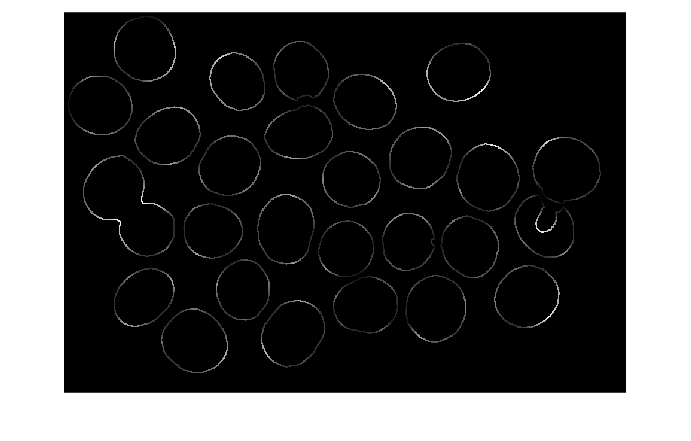


DTM = TD .* RI;

imshow(DTM, []);

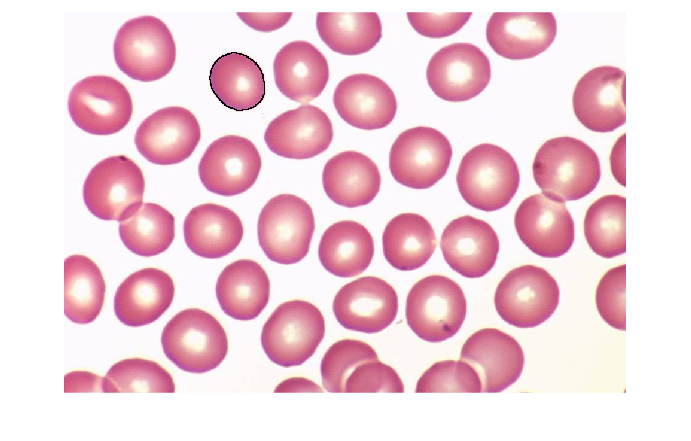

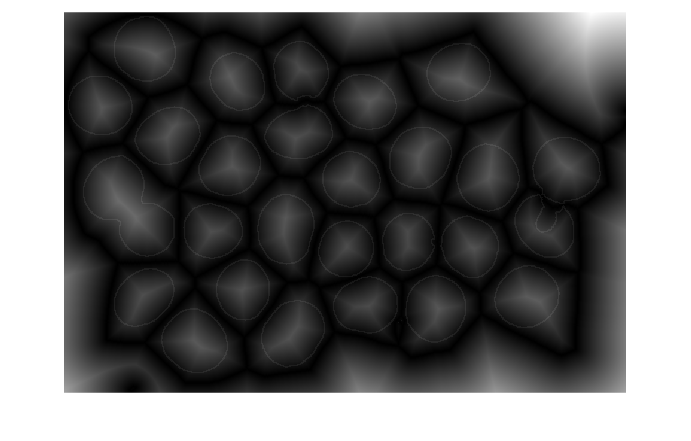


% components conectats
CC = bwconncomp(RI);

% cerca del mínim dels components connectats
for i = 1:CC.NumObjects
    dist(i) = min(TD(CC.PixelIdxList{i}));
end

[minim, pos] = max(dist);

R = RGB(:,:,1);

G = RGB(:,:,2);

B = RGB(:,:,3);

R(CC.PixelIdxList{pos}) = 0;
G(CC.PixelIdxList{pos}) = 0;
B(CC.PixelIdxList{pos}) = 0;

RGB(:,:,1) = R;
RGB(:,:,2) = G;
RGB(:,:,3) = B;

imshow(RGB);


imshow(TD + 10 * RI,[]);
